%Exercise 1
load('Inkjet.mat');
load('Dell.mat');

disp('Exercise 1')

Exercise 1


disp('Plot color gamut for  inkjet(red) and Dell-screen (green)')

Plot color gamut for  inkjet(red) and Dell-screen (green)


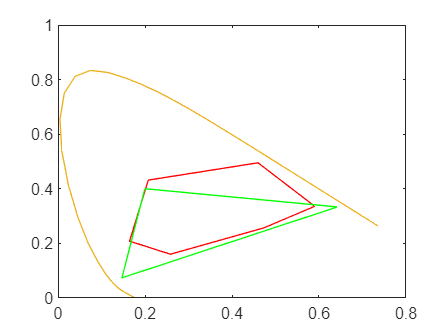



plot_chrom(XYZinkjet,'red');

%Color gamut:
                   %Grön
                                        %röd
                      %blå
plot_chrom(XYZdell, 'green');

%Exercise 2

%SNR - Signal Noise Ratio
%High value - Close to original
%Low value - Alot of noise, bigger difference 

disp('Exercise 2');

Exercise 2


disp('Different interpolations and snr-values')

Different interpolations and snr-values


%Read image, im2double scale image to be in interval [0,1]
image1 = im2double(imread('peppers_gray.tif'));

%Test
mysnr(image1,1);

%Apply different interpolations
nearest = imresize(imresize(image1,0.25,'nearest'),4,'nearest');
bilinear = imresize(imresize(image1,0.25,'bilinear'),4,'bilinear');
bicubic = imresize(imresize(image1,0.25,'bicubic'),4,'bicubic');

%Calculate SNR
nearest_snr = mysnr(image1, image1-nearest);
bilinear_snr = mysnr(image1,image1-bilinear);
bicubic_snr = mysnr(image1,image1-bicubic);


disp("Nearest snr " + nearest_snr);

Nearest snr 17.0956


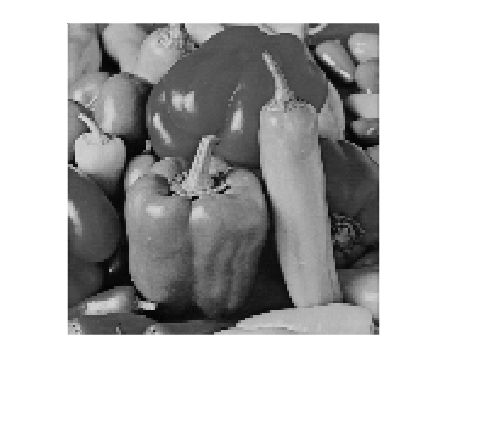

imshow(nearest);


disp("Bilinear snr " + bilinear_snr);

Bilinear snr 18.8922


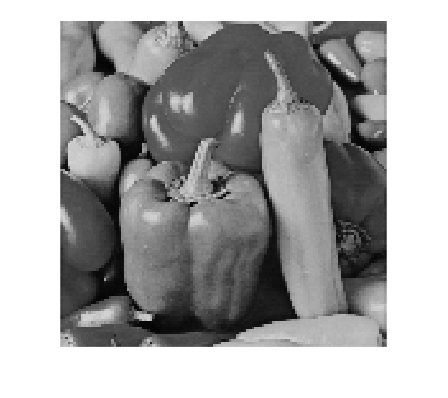

imshow(nearest);


disp("Bicubic snr " + bicubic_snr);

Bicubic snr 19.8538


imshow(nearest);

%Exercise 2.1.2
disp('Exercise 2.1.2');

Exercise 2.1.2


disp('Halftoning');

Halftoning



%Halftone via threshhold
%Boolean: 
% If value below 0.5 -> 0
%If value over 0.5 -> 1
image1_threshold = image1 >= 0.5;

%Halftone via error diffusion
image1_errorDiffusion = dither(image1);

%Calculate SNR-values
snr_threshold = mysnr(image1, image1 - image1_threshold);
snr_errorDiffusion = mysnr(image1, image1 - image1_errorDiffusion);

disp("Threshold snr: " + snr_threshold);

Threshold snr: 2.9721


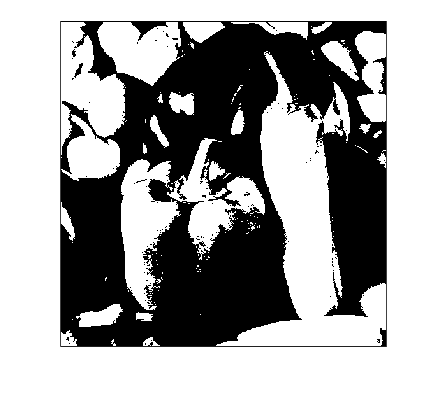

imshow(image1_threshold);


disp("Error diffusion: " + snr_errorDiffusion);

Error diffusion: 0.41121


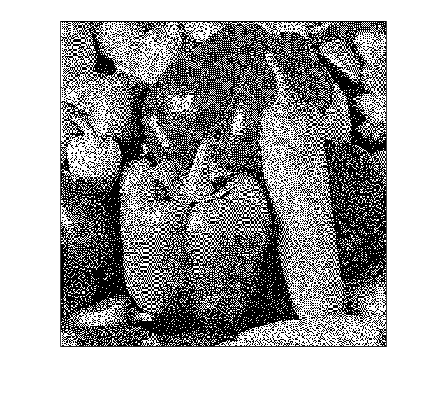

imshow(image1_errorDiffusion);

%Exercise 2.2
disp('Exercise 2.2');

Exercise 2.2


disp('Halftone and color difference for rgb-image')

Halftone and color difference for rgb-image



image2 = im2double(imread('peppers_color.tif'));

disp("Original rgb-image:");

Original rgb-image:


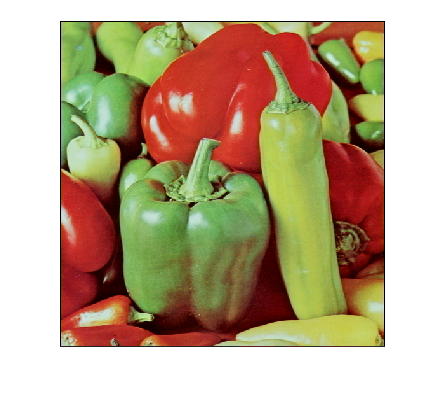

imshow(image2);


%Halftone by threshold

%Threshold the image
image2_threshold = image2 >= 0.5;

%Måste göras annars crashar koden
image2_threshold = double(image2_threshold);

halftoneR = image2_threshold(:,:,1);
halftoneG = image2_threshold(:,:,2);
halftoneB = image2_threshold(:,:,3);

%Combine the channels
thresh_RGB = cat(3,halftoneR,halftoneG,halftoneB);

disp('Halftoned image with threshold:')

Halftoned image with threshold:


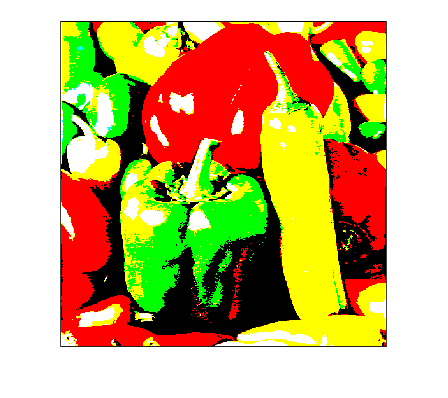

imshow(thresh_RGB);





%Halftone by error diffusion
halftoneR = double(dither(image2(:,:,1)));
halftoneG = double(dither(image2(:,:,2)));
halftoneB = double(dither(image2(:,:,3)));

errorDiffusion_RGB = cat(3,halftoneR,halftoneG,halftoneB);

disp('Halftoned image with error diffusion:')

Halftoned image with error diffusion:


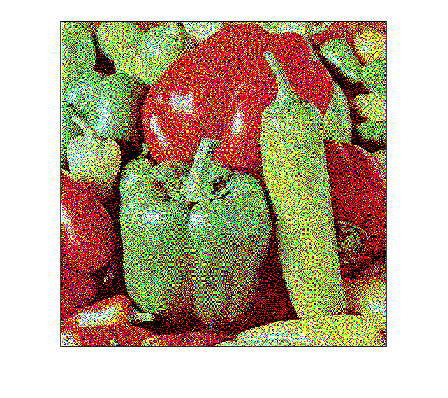

imshow(errorDiffusion_RGB);



%Convert to Lab
Lab_original = rgb2lab(image2);
Lab_threshold = rgb2lab(thresh_RGB);
Lab_errorDiffusion = rgb2lab(errorDiffusion_RGB);

%Calculate color difference
E1 = sum(ColorDiff2(Lab_original,Lab_threshold),'all')/(512*512);
E2 = sum(ColorDiff2(Lab_original,Lab_errorDiffusion),'all')/(512*512);


disp("Color difference for threshold: " + E1);

Color difference for threshold: 50.1577


disp("Color difference for error diffusion: " + E2);

Color difference for error diffusion: 72.8423


%Exercise 3
disp('Exercise 3');

Exercise 3


disp('SNR-filter values')

SNR-filter values


%Code copied from 2.1.2
image1_threshold = image1 >= 0.5;
image1_errorDiffusion = dither(image1);

%Calculate snr-filter values
snr_filter_threshold = snr_filter(image1, image1 - image1_threshold);
snr_filter_errorDiffusion = snr_filter(image1, image1 - image1_errorDiffusion);


disp("snr-filter value for threshold:" + snr_filter_threshold);

snr-filter value for threshold:3.3488


disp("snr-filter value for error diffusion:" + snr_filter_errorDiffusion);

snr-filter value for error diffusion:13.323


%Exercise 3 extended
disp('Exercise 3 extended');

Exercise 3 extended



image3 = im2double(imread('peppers_color.tif'));
disp('Original image');

Original image


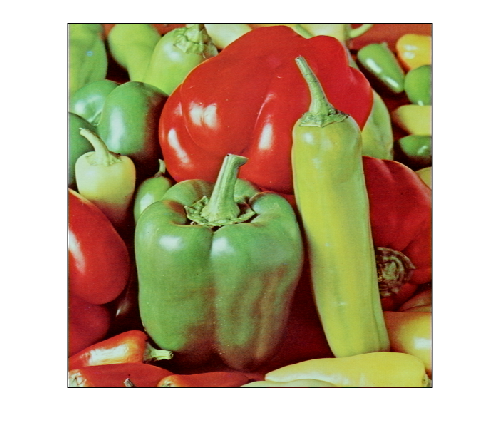

imshow(image3);


%Involve HVS model
f=MFTsp(15,0.0847,500);

%Separate the colorchannels
imageR = image3(:,:,1);
imageG = image3(:,:,2);
imageB = image3(:,:,3);

%Apply HVS model with f-kernel, 'same' -> Size unchanged
R=conv2(image3(:,:,1),f,'same');
G=conv2(image3(:,:,2),f,'same');
B=conv2(image3(:,:,3),f,'same');

%Set negative values to 0
R = (R>0).*R;
G = (R>0).*G;
B = (R>0).*B;

%Combine the channels to a image
image3_RGB = cat(3,R,G,B);

disp('Image after HVS-model is applied')

Image after HVS-model is applied


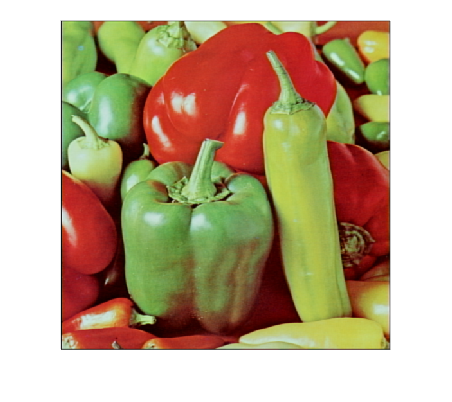

imshow(image3_RGB);


%Perform halftoning

%Halftone with threshold
image3_RGB_threshold = image3_RGB >= 0.5;

%Måste göras annars crashar koden
image3_RGB_threshold = double(image3_RGB_threshold);

halftoneR = image3_RGB_threshold(:,:,1);
halftoneG = image3_RGB_threshold(:,:,2);
halftoneB = image3_RGB_threshold(:,:,3);

%Apply the HVS-model
halftone1 =conv2(halftoneR,f,'same');
halftone2 =conv2(halftoneG,f,'same');
halftone3 =conv2(halftoneB,f,'same');

%Combine the channels
image3_threshold = cat(3,halftone1,halftone2,halftone3);

disp('Halftoned image with threshold:')

Halftoned image with threshold:


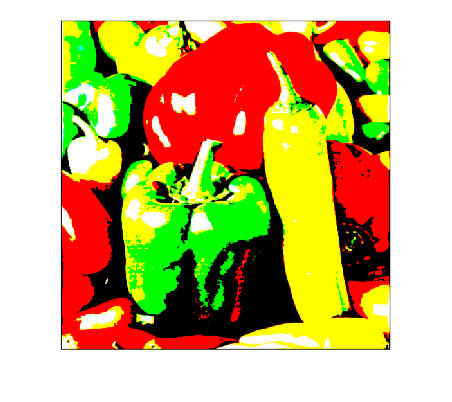

imshow(image3_threshold);


%Halftone with error diffusion
image3 = im2double(image3);
halftoneR = dither(image3(:,:,1));
halftoneG = dither(image3(:,:,2));
halftoneB = dither(image3(:,:,3));


%Apply the HSV-model
halftone1 =conv2(halftoneR,f,'same');
halftone2 =conv2(halftoneG,f,'same');
halftone3 =conv2(halftoneB,f,'same');

disp('Halftoned image with error diffusion:')

Halftoned image with error diffusion:


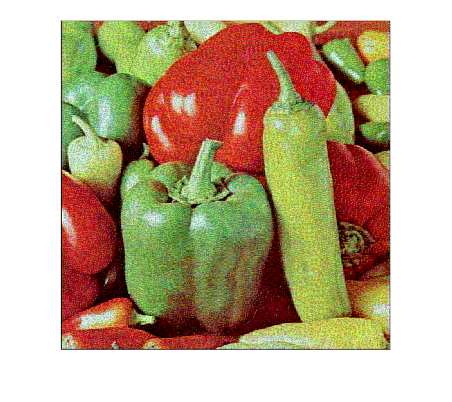

image3_errorDiffusion = cat(3,halftone1,halftone2,halftone3);
imshow(image3_errorDiffusion);


image3_Lab = rgb2lab(image3_RGB);
image3_threshold_Lab = rgb2lab(image3_threshold);
image3_errorDiffusion_Lab = rgb2lab(image3_errorDiffusion);

e1 = sum(ColorDiff2(image3_Lab,image3_threshold_Lab),'all')/(512*512);
e2 = sum(ColorDiff2(image3_Lab,image3_errorDiffusion_Lab),'all')/(512*512);

disp("Color difference for threshold: " + e1);

Color difference for threshold: 48.5514


disp("Color difference for error diffusion: " + e2);

Color difference for error diffusion: 20.2117


%Exercise 4
disp('Exercise 4');

Exercise 4


disp('S-CIELab');

S-CIELab



%My screen resolution 1536 x 864 pixels
%sicelab function arguments:
%Argument 1: sample per degree
%Argument 2: Original image
%Argument 3: reproduction in CIEXYZ
%Argument 4: Vector CIED65 = [95.05, 100, 108.9] (white point)
%Argument 5: Image format, xyz in this lab


%Read image, im2double scale image to be in interval [0,1]
image4 = im2double(imread('peppers_color.tif'));

%Interpolate as in Exercise 2
%Apply different interpolations

%Interpolate
nearest = imresize(imresize(image4,0.25,'nearest'),4,'nearest');
bilinear = imresize(imresize(image4,0.25,'bilinear'),4,'bilinear');
bicubic = imresize(imresize(image4,0.25,'bicubic'),4,'bicubic');

%Screen size: 14 inch (12,2 x 6,85
%Screen resolution: 1980x1080
%ppi = 1980/12,2 = 157ppi
%Viewing distance: 20inches (50cm)
ppi = 157;
d = 20;
sampPerDegree = ppi*d*tan(pi/180); %Lecture 3, slide 29
image4_xyz = rgb2xyz(image4); %Convert to xyz
CIED65 = [95.05, 100, 108.9]; %white point

%Compute scielab for the original image
original_scielab = scielab(sampPerDegree,image4,image4_xyz,CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


original_E = mean(original_scielab,'all');

%Compute scielab for the image with interpolation nearest
nearest_xyz = rgb2xyz(nearest);
nearest_scielab = scielab(sampPerDegree,nearest_xyz,image4_xyz,CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


nearest_E = mean(nearest_scielab,'all');

%Compute scielab for the image with interpolation bilinear
bilinear_xyz = rgb2xyz(bilinear);
bilinear_scielab = scielab(sampPerDegree,bilinear_xyz,image4_xyz,CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


bilinear_E = mean(bilinear_scielab,'all');

%Compute scielab for the image with interpolation bilinear
bicubic_xyz = rgb2xyz(bicubic);
bicubic_scielab = scielab(sampPerDegree,bicubic_xyz,image4_xyz,CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


bicubic_E = mean(bicubic_scielab,'all');

disp("S-CIELab original: " + original_E);

S-CIELab original: 8.3154


disp("S-CIELab nearest: " + nearest_E);

S-CIELab nearest: 0.18097


disp("S-CIELab bilinear: " + bilinear_E);

S-CIELab bilinear: 0.19187


disp("S-CIELab bicubic: " + bicubic_E);

S-CIELab bicubic: 0.12013


%Exercise 4.2

disp('Exercise 4.2');

Exercise 4.2


disp('Standard deviation');

Standard deviation


load('colorhalftones.mat');

disp('c1');

c1


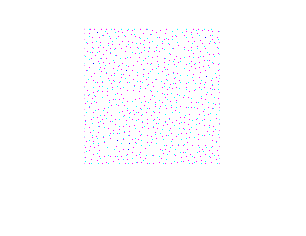

imshow(c1);

disp('c2');

c2


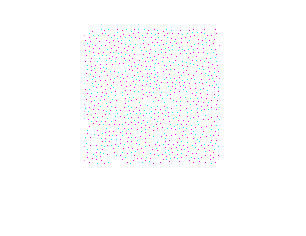

imshow(c2);

disp('c3');

c3


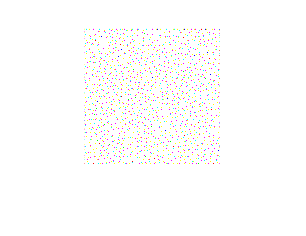

imshow(c3);

disp('c4');

c4


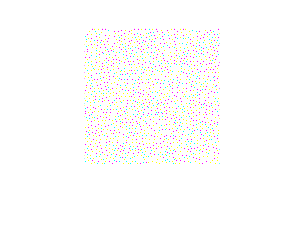

imshow(c4);

disp('c5');

c5


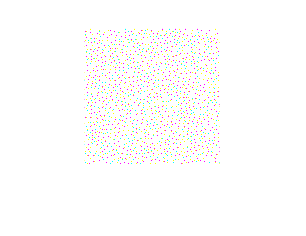

imshow(c5);



%Convert to xyz
c1_xyz = rgb2xyz(c1);
c2_xyz = rgb2xyz(c2);
c3_xyz = rgb2xyz(c3);
c4_xyz = rgb2xyz(c4);
c5_xyz = rgb2xyz(c5);

%Calculate scielab
c1_scielab = scielab(sampPerDegree,c1_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c2_scielab = scielab(sampPerDegree,c2_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c3_scielab = scielab(sampPerDegree,c3_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c4_scielab = scielab(sampPerDegree,c4_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c5_scielab = scielab(sampPerDegree,c5_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...



%Calculate standrard deviation
% matrix A is sum of the sum of L,a,b channels
c1_std = std2(c1_scielab(:,:,1)+c1_scielab(:,:,2)+c1_scielab(:,:,3));
c2_std = std2(c2_scielab(:,:,1)+c2_scielab(:,:,2)+c2_scielab(:,:,3));
c3_std = std2(c3_scielab(:,:,1)+c3_scielab(:,:,2)+c3_scielab(:,:,3));
c4_std = std2(c4_scielab(:,:,1)+c4_scielab(:,:,2)+c4_scielab(:,:,3));
c5_std = std2(c5_scielab(:,:,1)+c5_scielab(:,:,2)+c5_scielab(:,:,3));

%Display the result
disp("Standard deviation for c1: " + c1_std);

Standard deviation for c1: 0.020168


disp("Standard deviation for c2: " + c2_std);

Standard deviation for c2: 0.016749


disp("Standard deviation for c3: " + c3_std);

Standard deviation for c3: 0.020759


disp("Standard deviation for c4: " + c4_std);

Standard deviation for c4: 0.016727


disp("Standard deviation for c5: " + c5_std);

Standard deviation for c5: 0.016836


%Exercise 5

%ssim: 
% Input: original and distorted image
%Output: strctural similarity image

%SSIM - Measurement how similar to images are with light, structure and
%contrast
%1 - images are the same
%0 - images are very different

disp('Exercise 5');

Exercise 5


disp('SSIM');

SSIM



image5 = im2double(imread("peppers_gray.tif"));

distortion1 = im2double(image5);
distortion2 = im2double(image5);
size = 512;

%a)

%Distortion 1
for n = 1:1:size

    %Add 0.1 to odd rows and subtract 0.1 from even rows
    if mod(n,2) ~= 0
       distortion1(n,:) = distortion1(n,:) + 0.1;
    else
        distortion1(n,:) = distortion1(n,:) - 0.1;
    end
end

%Distortion 2
for n = 1:1:256
    %Add 0.1 to upper half
    for m = 1:1:512
        distortion2(n,m) = distortion2(n,m) + 0.1;
    end
end
for n = 257:1:512
    %Subtract 0.1 to lower half
    for m = 1:1:512
        distortion2(n,m) = distortion2(n,m) - 0.1;
    end
end

snr_distortion1 = mysnr(image5,distortion1 - image5);
snr_distortion2 = mysnr(image5,distortion2 - image5);


% [ssimval, ssimmap] = ssim(A,ref);

 [ssimval_distortion1, ssimmap_distortion1] = ssim(image5,distortion1);
 [ssimval_distortion2, ssimmap_distortion2] = ssim(image5,distortion2);

 disp('Distortion 1: Add 0.1 to odd rows, subtract 0.1 to even rows')

Distortion 1: Add 0.1 to odd rows, subtract 0.1 to even rows


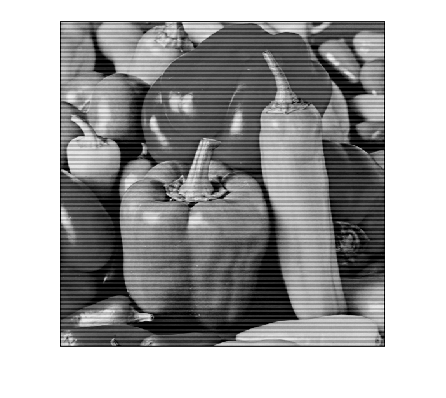

imshow(distortion1);


disp('Distortion 1: Add 0.1 to upper half, subtract 0.1 to lower half')

Distortion 1: Add 0.1 to upper half, subtract 0.1 to lower half


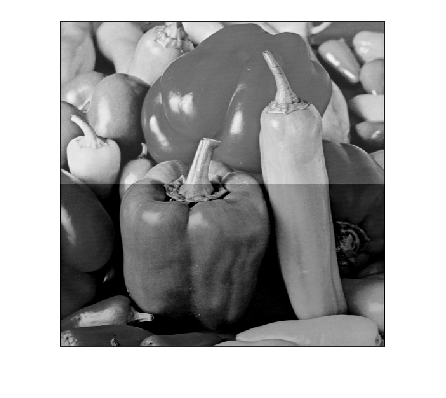

imshow(distortion2)


disp("Distortion 1 snr: " + snr_distortion1);

Distortion 1 snr: 13.4303


disp("Distortion 2 snr: " + snr_distortion2);

Distortion 2 snr: 13.4303



disp("Distortion 1 ssim-value: " + ssimval_distortion1);

Distortion 1 ssim-value: 0.24354


disp("Distortion 2 ssim-value: " + ssimval_distortion2);

Distortion 2 ssim-value: 0.85276



%b)

%Add noise to original image
distortion3 = image5 + 0.2 * (rand(512) - 0.5);

disp('Distortion 3: Add random noise')

Distortion 3: Add random noise


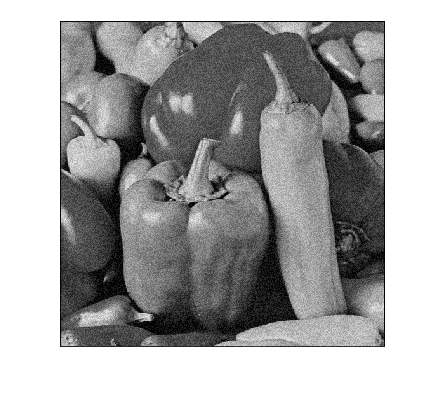

imshow(distortion3)

%Gaussian filter
 f=fspecial('gauss',21,10);
 
 %Apply the filter to the original image with f-kernel
distortion4 = conv2(image5,f,'same');
disp('Distortion 4: Apply Gaussian filter')

Distortion 4: Apply Gaussian filter


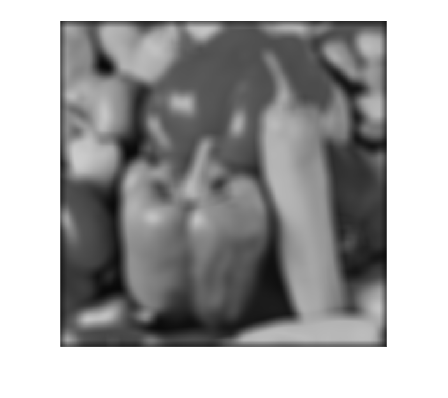

imshow(distortion4)


%Calculate snr
snr_distortion3 = mysnr(image5, distortion3-image5);
snr_distortion4 = mysnr(image5, distortion4-image5);

%Calculate ssim
[ssimval_distortion3, ssimmap_distortion3] = ssim(image5,distortion3);
[ssimval_distortion4, ssimmap_distortion4] = ssim(image5,distortion4);

disp("Distortion 3 snr: " + snr_distortion3);

Distortion 3 snr: 18.2


disp("Distortion 4 snr: " + snr_distortion4);

Distortion 4 snr: 14.9577



disp("Distortion 3 ssim-value: " + ssimval_distortion3);

Distortion 3 ssim-value: 0.43362


disp("Distortion 4 ssim-value: " + ssimval_distortion4);

Distortion 4 ssim-value: 0.67729
